clear all;
tbUseProject('ISETTreeShrew');

Locating project "ISETTreeShrew" within "C:\Users\eemeyer\Documents\MATLAB\projects".
  Found at "C:\Users\eemeyer\Documents\MATLAB\projects\ISETTreeShrew".
Local copy of ToolboxToolbox is up to date.
Updating "ToolboxRegistry".
Already up to date.
Obtaining "ISETTreeShrew".
fatal: destination path 'C:\Users\eemeyer\Documents\MATLAB\projects\ISETTreeShrew' already exists and is not an empty directory.
Updating "isetbio".
From https://github.com/isetbio/isetbio
   028c0561..43bd2eaf  master     -> origin/master
Updating 028c0561..43bd2eaf
Fast-forward
 LSF_Artal2012_1.png                                | Bin 55348 -> 0 bytes
 .../eccentricitiesForQuadrant.m                    |  59 ------------
 ...estimateConeCharacteristicRadiusInVisualSpace.m |   3 +-
 calculators/demoRetinaToVisualFieldTransformer.m   | 100 +++++++++++++--------
 isettools/cones/@cMosaic/cMosaic.m                 |   6 ++
 .../eccentricitiesForRetinaMeridianInEye.m         |  50 +++++++++++
 testmosaic.mat          

[theWVFOI,wvfP2] = oiTreeShrewCreate('opticsType', 'wvf', ...
    'name', 'wvf-based optics');


% from opticsTreeShrewDefaultParams
opticstype = 'wvf';
focalLengthMM = 4.35;
pupilDiameterMM = 3.0;

% from opticsTreeShrewCreate
opticsName = 'wvf-based optics';
wavelengthSupport = 400:10:700;

focalLengthMeters = focalLengthMM / 1000;
posteriorNodalDistanceMM = focalLengthMM;
micronsPerDegree = posteriorNodalDistanceMM * 1000 * tand(1);
optics.micronsPerDegree = micronsPerDegree;

optics.type = 'optics';
optics = opticsSet(optics, 'model', 'shiftInvariant');

% from opticsTreeShrewCreate/opticsFromTreeShrewZCoefs
measuredDiameterMM_TreeShrew = 4.0;

% 840 nm light used in measurements of Sajdak et al 2019 (section 2.2)
measuredWavelenth = 840;

% read in Zernicke coefficients as matrix
% zCoeffs = cell2mat(readcell('Tree_Shrew_Aberrations_Remeasured_Oct2018.xlsx','Range','B7:L71'));
spatialsamples = 1001;

% Defocusm with coefficient #4, (#5 in Matlab' indexing) is by far the dominant Zcoeffs in measurents of Sajdak et al 2019
% So we are setting all the other coeffs to 0.
% The data here are from Figure 2 of Sajdak et al 2019

% zCoeffs_TreeShrew = randn(1,size(zCoeffs,1)+1)*0.0;
% zCoeffs_TreeShrew(2:end) = zCoeffs(:,ii);

zCoeffs_TreeShrew = randn(1,20)*0.0;
%zCoeffs_TreeShrew(4) = -0.15;
zCoeffs_TreeShrew(5) = -2.75;

wvfP = wvfCreate(...
    'spatialsamples', spatialsamples, ...
    'measured wl', measuredWavelenth, ... 
    'calc wavelengths', wavelengthSupport, ...
    'zcoeffs', zCoeffs_TreeShrew, ...
    'name', sprintf('treeshrew-%d', pupilDiameterMM), ...
    'umPerDegree', micronsPerDegree,...
    'customLCA', @treeShrewLCA);

wvfP = wvfSet(wvfP, 'measured pupil size', measuredDiameterMM_TreeShrew);
wvfP = wvfSet(wvfP, 'calc pupil size', pupilDiameterMM);
wvfP = wvfComputePSF(wvfP);
    
optics = oiGet(wvf2oi(wvfP), 'optics');

% Set the optics name
optics.name = opticsName;

% Set the focal length
optics = opticsSet(optics, 'focalLength', focalLengthMeters);

% Set the f-Number.
optics = opticsSet(optics, 'fnumber', focalLengthMeters*1000/pupilDiameterMM);

% cos-4th off-axis attenuation
optics = opticsSet(optics, 'offAxisMethod', 'cos4th');

% Pixel vignetting is off
optics.vignetting =  0;


% from oiTreeShrewCreate
oi.type = 'opticalimage';
oi = oiSet(oi, 'optics', optics);
oi = oiSet(oi, 'name', 'treeshrew');

oi = oiSet(oi, 'bit depth', 32);
oi = oiSet(oi, 'diffuser method', 'skip');
oi = oiSet(oi, 'consistency', 1);


% from lensTreeShrewCreate
% TreeShrew lens absorption.
lensAbsorbanceFile = 'treeshrewLensAbsorbance.mat';
targetWavelenth = wavelengthSupport;

% TreeShrew lens absorption. Start with the human lens.
theLens = Lens();

% Load TreeShrew lens unit-density
load(lensAbsorbanceFile, 'wavelength', 'data');

if (isempty(targetWavelenth))
    targetWavelenth = wavelength;
    unitDensity = data;
else
    % Interpolate to optics wavelength support
    unitDensity = interp1(wavelength,data,targetWavelenth, 'pchip');
end

% Update the lens
set(theLens,'wave', targetWavelenth);
set(theLens,'unitDensity',unitDensity);


% from oiTreeShrewCreate
% Update the oi.lens
oi = oiSet(oi, 'lens', theLens);

% Set the same lens in the optics structure too
oi.optics.lens = theLens;


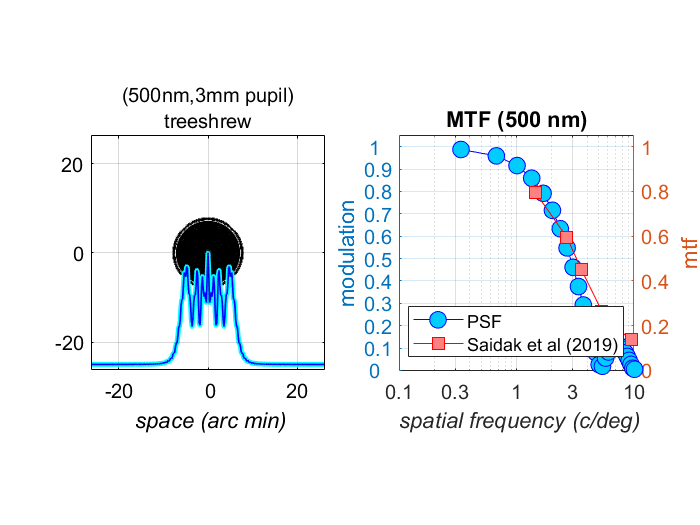

visualizedSpatialSupportArcMin = 50;
visualizedSpatialSfrequencyCPD = 10.0;

visualizeOptics(theWVFOI, 500, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));


visualizeOptics(oi, 500, ...
    visualizedSpatialSupportArcMin, ...
    visualizedSpatialSfrequencyCPD, ...
    'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));

function lcaDiopters = treeShrewLCA(wl1NM, wl2NM)
    % We dont have a model LCA for tree shrew yet.
    % Here we model is as the human LCA x 5
    % This creates an LCA difference between 840nm and 550nm of -4.5D
    % as per Sadjak et al (2019), "Noninvasive imaging of the tree shrew eye:
    % Wavefront analysis and retinal imaging with correlative histology"
    
    constant = 1.8859 - (0.63346 ./ (0.001 .* wl1NM - 0.2141));
    lcaDiopters = 1.8859 - constant - (0.63346 ./ (0.001 * wl2NM - 0.2141));
    lcaDiopters = 5.15 * lcaDiopters;
end